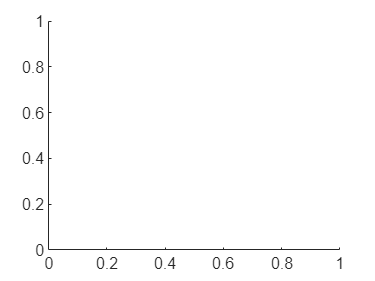

% myTracker,  codi inicial del short project

close all

% Llegim el fitxer d'anotacions groundtruth_rect.txt: frame, bounding boxes, is_lost
BB = importdata('MotorcycleChase/groundtruth_rect.txt');
Idir = dir('MotorcycleChase/img/*.jpg');

figure
hold on % mantenim sempre oberta la mateixa figura


% filtre de Kalman
initialStateP = [BB(1,2) 0 BB(1,3) 0]; % posicio inicial i velocitat
initialStateW = [BB(1,4) 0 BB(1,5) 0]; % mida inicial i velocitat
KFP = trackingKF('MotionModel','2D Constant Velocity','State',initialStateP);

'trackingKF' requires one of the following:
  Automated Driving Toolbox
  Sensor Fusion and Tracking Toolbox
  Radar Toolbox

KFW = trackingKF('MotionModel','2D Constant Velocity','State',initialStateW);

nf = size(Idir); % nombre total de fitxers imatges
for i = 1:nf
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I = imread(filename);
    
    predP = predict(KFP); % predictor de la posicio de la finestra per Kalman
   
    correct(KFP,BB(i,2:3)); % indiquem la nova posicio detectada
    
    predW = predict(KFW); % predictor de l'amplada/alcada de la finestra per Kalman
   
    correct(KFW,BB(i,4:5));

    %calculem el –overlap, intersection over union-- de les finestres 
    overlapRatio = bboxOverlapRatio([predP(1),predP(3),predW(1),predW(3)],BB(i,2:5))

    % mostrem els resultats sobre la imatge
    imshow(I); % mostra el frame 
    % mostrem els rectangles:  correcte (en groc) i el predit (en vermell)
    rectangle('Position',[predP(1),predP(3),predW(1),predW(3)],'EdgeColor','red');
    rectangle('Position',BB(i,2:5),'EdgeColor','yellow');
    drawnow
end

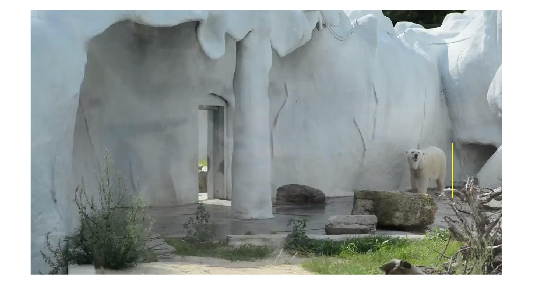

% Llegim el fitxer d'anotacions groundtruth_rect.txt: frame, bounding boxes, is_lost
BB = importdata('PolarBear1/groundtruth_rect.txt');
Idir = dir('PolarBear1/img/*.jpg');

scale = 1;

nf = size(Idir); % nombre total de fitxers imatges
i = 1;
filename = horzcat(Idir(i).folder,'/',Idir(i).name);
I = imresize(imread(filename), scale);

%rect = [BB(1, 2), BB(1, 3), BB(1, 2) + BB(1, 4), BB(1, 3) + BB(1, 5)]
rect = [BB(1, 2)*scale, BB(1, 3)*scale, BB(1, 4)*scale, BB(1, 5)*scale];
IC = imcrop(I, rect);


IQ = insertShape(I, 'Rectangle', rect);
imshow(IQ);

overlapRatio = 0.9480

overlapRatio = 0.8992

overlapRatio = 0.8602

overlapRatio = 0.8348

overlapRatio = 0.7962

overlapRatio = 0.7591

overlapRatio = 0.7342

overlapRatio = 0.7099

overlapRatio = 0.6931

overlapRatio = 0.6942

overlapRatio = 0.6839

overlapRatio = 0.7018

overlapRatio = 0.7146

overlapRatio = 0.7481

overlapRatio = 0.7742

overlapRatio = 0.7937

overlapRatio = 0.7945

overlapRatio = 0.7936

overlapRatio = 0.7848

overlapRatio = 0.7709

overlapRatio = 0.7504

overlapRatio = 0.7246

overlapRatio = 0.7084

overlapRatio = 0.6843

overlapRatio = 0.6701

overlapRatio = 0.6670

overlapRatio = 0.6570

overlapRatio = 0.6510

overlapRatio = 0.6414

overlapRatio = 0.6300

overlapRatio = 0.6306

overlapRatio = 0.6295

overlapRatio = 0.6234

overlapRatio = 0.6252

overlapRatio = 0.6157

overlapRatio = 0.6066

overlapRatio = 0.5981

overlapRatio = 0.5871

overlapRatio = 0.5809

overlapRatio = 0.5753

overlapRatio = 0.5773

overlapRatio = 0.5844

overlapRatio = 0.5908

overlapRatio = 0.5975

overlapRatio = 0.6058

overlapRatio = 0.6156

overlapRatio = 0.6199

overlapRatio = 0.6080

overlapRatio = 0.6017

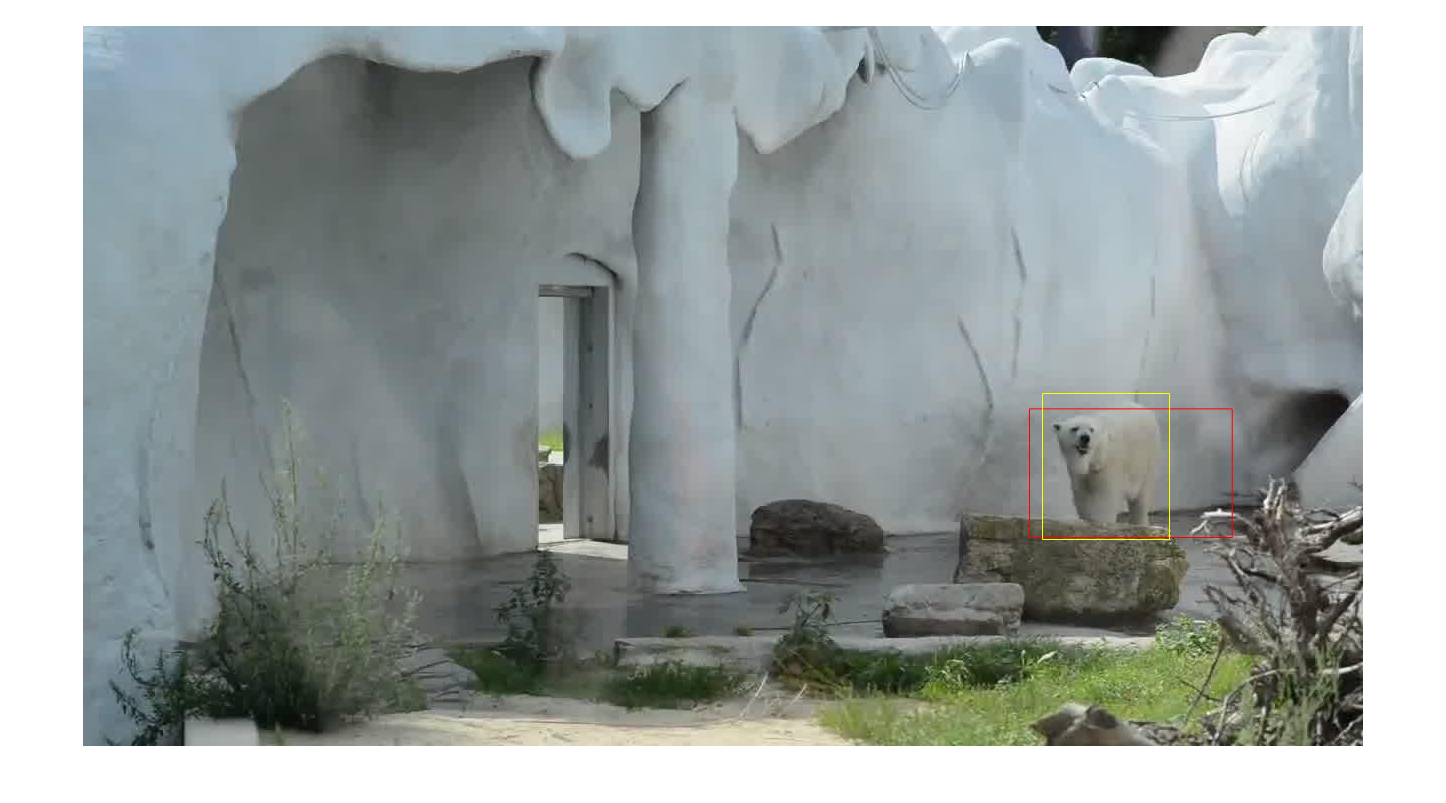


for i = 2:50
    im_obj = rgb2gray(IC);
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I2 = imresize(imread(filename), scale);
    im_esc = rgb2gray(I2);
    %montage({im_obj, im_esc});
    
    kp_obj = detectSIFTFeatures(im_obj);
    kp_esc = detectSIFTFeatures(im_esc);
    
    [feat_obj, kp_obj] = extractFeatures(im_obj, kp_obj, "Method", "SIFT");
    [feat_esc, kp_esc] = extractFeatures(im_esc, kp_esc, "Method", "SIFT");
    
    pairs = matchFeatures(feat_obj, feat_esc, "MatchThreshold",10);
    
    m_kp_obj = kp_obj(pairs(:,1),:);
    m_kp_esc = kp_esc(pairs(:,2),:);
    
    %figure
    %showMatchedFeatures(im_obj, im_esc,m_kp_obj, m_kp_esc, "montage");
    
    T = estimateGeometricTransform2D(m_kp_obj,m_kp_esc,'affine');
    
    [f, c] = size(im_obj);

    box = [1,1 ; 1,f ; c,f ; c,1 ; 1,1];

    nbox = transformPointsForward(T, box);
    bbox = [nbox(1, :), nbox(3, :) - nbox(1, :)];
    IC = imcrop(I2, bbox);
    
    %IQ = insertShape(I2, 'Rectangle', bbox(1, :));
    %imshow(IQ);

    %calculem el –overlap, intersection over union-- de les finestres 
    overlapRatio = bboxOverlapRatio(bbox(1, :),BB(i,2:5).*scale)


    % mostrem els resultats sobre la imatge
    imshow(I2); % mostra el frame 
    % mostrem els rectangles:  correcte (en groc) i el predit (en vermell)
    rectangle('Position',bbox(1, :),'EdgeColor','red');
    rectangle('Position',BB(i,2:5).*scale,'EdgeColor','yellow');
    drawnow
end